# Data Cleaning Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 18/04/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Enviroment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Set Directories **

Set path to function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/dataprocessing/functions/'));

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Exploration/',exportName);

Set Processed data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Data Pre-Processing

trying to fix SAGDP issues at an import level

% opts = detectImportOptions(fileName)
% disp([opts.VariableNames' opts.VariableTypes'])
% opts.VariableTypes{2} = 'double'; 
% disp([opts.VariableNames' opts.VariableTypes'])

% define columns to keep from each sheet
% varsToKeep = {'PX_LAST'};
% % create sheetName var to loop through in the file
% excelSheetNames = sheetnames(fileName);
% % Preallocate cell array for storage before looping
% SIG_data = cell(size(excelSheetNames));
% % Load the dataset by sheet
% for sheet = 1:numel(excelSheetNames)
%     % Read the sheet and filter for numeric variables only
%     sheetData = readtable(fileName, 'Sheet', excelSheetNames{sheet}, 'Range', 'A6', 'VariableNamingRule', 'preserve', 'VariableNamesRange', 'A6');
%     sheetData = sheetData(:,isnumeric(sheetData{:, :}));
%     % Keep only columns specified in varsToKeep
% %     sheetData = sheetData(:,varsToKeep);
%     % Convert to timetable object and assign the ticker as the timetable Description
% %     SIG_data{sheet} = table2timetable(sheetData, 'RowTimes', 1:size(sheetData,1), 'Description', excelSheetNames{sheet});
% end

### 2.1 SIGNAL DATA: Load data (works but SAGDP is char)

fileName = "DATA-BB-SIG-M-20000223-20230323.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/SIGNAL',fileName);

Import per sheet and only keep certain field. importfields2keep only needed when excel has multiple sheets to import from. 

tickers2keep = {'PX_LAST'};
SIGSheetNames = sheetnames(fileName);
SIG_data = importfields2keep(tickers2keep,fileName);

#### 2.1.1 Address data types and frequencies

- SA GDP data type has text due to the NAs imported. Needs to be changed to numeric. 

- SA GDP data is Quarterly -> needs to be changed using cubic-spline interpolation to monthly points

% Replace '#N/A N/A' with NaN
SAGDP_table = SIG_data{2}

for entry = 1:height(SAGDP_table)
    if strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')       
        SAGDP_table.PX_LAST{entry} = str2num('NA');
%         = str2double(SAGDP_table{entry,1});
%     elseif ischar(SAGDP_table{entry,1}{1})
%         SAGDP_table{entry,1}{1} = strrep(SAGDP_table{entry,1}{1}, ',', '.');
%         SAGDP_table{entry,1} = str2double(SAGDP_table{entry,1}{1});
    end
end 
% 
% for entry = 1:height(SAGDP_table)
% 
%     if strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')       
%         SAGDP_table{entry,1} = {NaN};
% %     elseif SAGDP_table{entry,1}{1} == isa(SAGDP_table{entry,1}{1},'char')
% %          SAGDP_table{entry,1} = str2double(SAGDP_table{entry,1}{1});
%     end
% end
SAGDP_table
% strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')) = SAGDP_table{entry,1}
% % Replace '#N/A N/A' with NaN
% SAGDP_table(strcmp(SAGDP_table{:,1}{1}, '#N/A N/A')) = {NaN};
% 
% Convert remaining values to doubles
% SAGDP_table{:,1} = str2double(SAGDP_table{:});

% % Replace any empty cells with NaN
% SAGDP_table(cellfun(@isempty, SAGDP_table)) = {NaN};

#### 2.1.2 Clean and convert into a single timetable by synchronize dates

% Synchronize all timetable objects in the cell array
SIG_dataTable = synchronize(SIG_data{:});
% rename variables
SIG_dataTable.Properties.VariableNames = SIGSheetNames;
% Display the synchronized timetable
disp(SIG_dataTable);

%######## Dropping GDP for now until ######3
SIG_dataTable = removevars(SIG_dataTable, "SAGDPANN Index");

When looking at the timetable we notice that there are inconsistencies with when certain signal indices are reported. 

#### 2.1.3 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index"};
na_array = transpose(isnan(table2array(SIG_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:12,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Signals");
xlabel("Date Index");
title("Missing Data PRE Date Alignment");
sig_NAplot = gca;
hold off

**Export NA Data plot**

exportName = 'SIG_NAdata_plot.pdf';
exportgraphics(sig_NAplot,fullfile(imageExportpath,exportName),'Resolution',300);


#### 2.1.4 Exporting sample chunck of Misaligned data 

- to change to latex table for reporting

% Set time range to subset
TR_general = timerange('30-Sep-2009','31-Dec-2010');
sig_sample_tab = SIG_dataTable(TR_general,:);
%  = tail(SIG_dataTable)
% writetimetable(sig_sample_tab,'sig_sample_tab.xlsx');

#### 2.1.5 Fixing the inconsistent dates in the timetable objects

 Shift the timedate array of the individual state signal variables before synchronizing.

for signal = 1:width(SIG_data)
    SIG_data{1,signal}.Dates = dateshift(SIG_data{1,signal}.Dates, 'end', 'month');
end
SIG_aligned_data = SIG_data;

% Synchronize timetable objects 
SIG_aligned_dataTable = synchronize(SIG_aligned_data{:});
% rename variables
SIG_aligned_dataTable.Properties.VariableNames = SIGSheetNames;
% Display the synchronized timetable
disp(SIG_aligned_dataTable);

%######## Dropping GDP for now until ######3
SIG_aligned_dataTable = removevars(SIG_aligned_dataTable, "SAGDPANN Index");

Plotting date adjusted data for signal data


% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index"};
na_array = transpose(isnan(table2array(SIG_aligned_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:12,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Signals");
xlabel("Date Index");
title("Test Missing Data POST date alignment");
sig_alignedPlot = gca;

**Export NA Data plot**

exportName = 'SIG_alignedData_plot.pdf';
exportgraphics(sig_alignedPlot,fullfile(imageExportpath,exportName),'Resolution',300);
close all

**Extract the names of cols to change to valid field names (remove ' ',replace with '_')**

% rename the variables with underscores instead of spaces
newNames = strrep(SIG_aligned_dataTable.Properties.VariableNames, ' ', '_');
SIG_aligned_dataTable = renamevars(SIG_aligned_dataTable, SIG_aligned_dataTable.Properties.VariableNames, newNames);

**SAVE Processed SIGNAL Datasets:**

exportName = 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
save(fullfile(dataExportpath,exportName),'SIG_aligned_dataTable');

### 2.2 ASSET CLASS DATA: Load data: Automate file imports 

Import data from excel spreed sheet built using Bloomberg Terminal 

 **Indices**: 

Market Sectors

Financials -> Fini TRI

Industrial -> Indi TRI

Resources -> Resi TRI

Bonds -> Albi TRI

**Set Directories **

% use your default user path to create the filename and path
fileName = "DATA-BB-ASSETCL-IDX-M-20000223-20230323.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/ASSETCLASS',fileName);

**Import from single sheet**

ASSETCL_dataTable = readtimetable(fileName, VariableNamingRule='preserve', VariableNamesRange ='A4', VariableDescriptionsRange = 'B5',Range='A4');

#### 2.2.1 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

% missing data to plot in array
tickers = ASSETCL_dataTable.Properties.VariableNames;
na_array = transpose(isnan(table2array(ASSETCL_dataTable)));
ax = axes;

spy(na_array, 'black-',5);
set(gca,'ytick',1:5,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Assets");
xlabel("Date Index");
title("Missing Data");
assetcl_NAplot = gca;
close all

**Export NA Data plot**

exportName = 'ASSETCL_NAdata_plot.pdf'

exportName = 'ASSETCL_NAdata_plot.pdf'

exportgraphics(assetcl_NAplot,fullfile(imageExportpath,exportName),'Resolution',300)

Error using exportgraphics
First parameter must specify the axes or chart object.

**Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

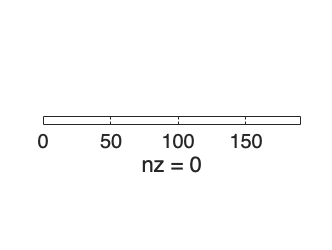

[countNans,idx] = max(sum(isnan(ASSETCL_dataTable{:,:}),1));
rmmissingProxy =  ASSETCL_dataTable.Properties.VariableNames{idx};
ASSETCL_TableFilled = rmmissing(ASSETCL_dataTable,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(ASSETCL_TableFilled))))

**Extract the names of cols to change to valid field names (remove ' ',replace with '_')**

% rename the variables with underscores instead of spaces
newNames = strrep(ASSETCL_TableFilled.Properties.VariableNames, ' ', '_');
ASSETCL_TableFilled = renamevars(ASSETCL_TableFilled, ASSETCL_TableFilled.Properties.VariableNames, newNames);

**SAVE Processed ASSETCL Datasets:**

exportName = 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';
save(fullfile(dataExportpath,exportName),'ASSETCL_TableFilled');

## 3. Data Transformation

### 3.1 Compute Returns  

RESI_ret = 100*price2ret(ASSETCL_dataTable.("RESI20TR Index"))
scatter(ASSETCL_dataTable.Time(1:end-1),RESI_ret);
ytickformat('percentage');
title('RESI20 Index Returns');
ylabel('Returns');

## 4. Data Expoloration

### 4.1 SIGNAL Data Exploration

### 4.2 ASSET CLASS Data Exploration

### 4.2.1 Plot Market Segment TRIs

% Visualise the data on a single plot
%plot the timeseries
% Create multiple line objects using matrix input to plot
plot1 = plot(ASSETCL_dataTable.Time,ASSETCL_dataTable{:,2:4},'LineWidth',1.5);
set(plot1(1),'DisplayName','FINI15TR Index');
set(plot1(2),'DisplayName','INDI25TR Index');
set(plot1(3),'DisplayName','RESI20TR Index');
ylabel("TRIs")
% Create title
title('TRI for SA Market Segments','FontSize',16);
%include the legend
% Create legend
legend1 = legend(ASSETCL_dataTable.Properties.VariableNames{:,2:4},'show');
set(legend1,'Location','northwest','FontSize',12);

MARKETSEG_TRI_plot = gca;

4.2.2 

Export Market Segment Returns plot

exportName = 'MARKETSEG_TRI_plot.pdf'
exportgraphics(MARKETSEG_TRI_plot,fullfile(imageExportpath,exportName),'Resolution',300)

# tick2ret

Convert price series to return series

% [resi_returns,resi_intervals] = tick2ret(bloomberg__ticker_market_data__resi20_index)
% % subplot(4,1,1);
% ax = axes;
% spy(transpose(isnan(table2array(resi_returns))));
% ylabel("Assets Index")
% xlabel("Date Index")
% title("Missing Data")
% % [left bottom width height]
% ax.OuterPosition = [ax.OuterPosition(1:3) ax.OuterPosition(4)];

## Addional Build-On's 

- Code in checks eg:

- if files exist

- checking sequencial nature of dates (eg code way of confirming no missing date or if the spacing isn't desired frequency like monthly

         2.    Increase function flexibility:

-  see if we can make the functions more sufficiticated to be cope to a wider range of inputs (eg importfield2keep is very specific in what it generates as a lot is hard coded).

          3. Change file names to save using info from varaibles eg:

-  saving .mat files using function that pulls START and END date from the data and not entered manually.

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)